# Calculate circular summary statistics

Generate a random array of angles ranging between (-pi/2) and (pi/2)

angs = rand(1,1000);
angs = (angs*pi)-(pi/2);

Visualize the data

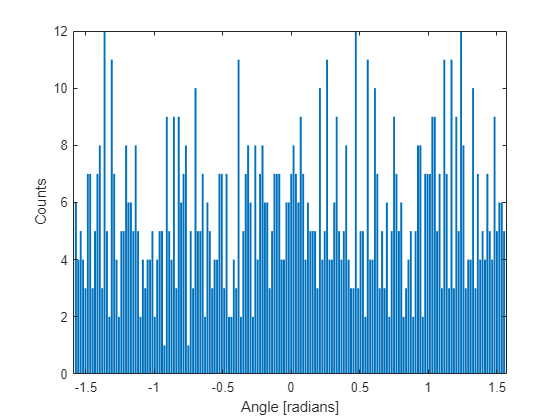

figure; bar((-pi/2:pi/180:pi/2-(pi/180)),histcounts(angs,(-pi/2:pi/180:pi/2)));
ylabel('Counts'); xlabel('Angle [radians]');

Calculate the (non-weighted) mean direction and directional variance

[meanc,varc,~] = circmean2(angs,ones(size(angs)));
disp(['Mean Direction: ',num2str(meanc*(180/pi),3),' degrees.'])

Mean Direction: 46 degrees.


disp(['Directional Variance: ',num2str(varc,3),'.'])

Directional Variance: 0.97.
